# Stereo Visual SLAM for UAV Navigation in 3D Simulation

*Visual SLAM* is the process of calculating the position and orientation of a camera with respect to its surroundings while simultaneously mapping the environment. Developing a visual SLAM algorithm and evaluating its performance in varying conditions is a challenging task. One of the biggest challenges is generating the ground truth of the camera sensor, especially in outdoor environments. The use of simulation enables testing under a variety of scenarios and camera configurations while providing precise ground truth.

This example demonstrates the use of Unreal Engine® simulation to develop a visual SLAM algorithm for a UAV equipped with a stereo camera in a city block scenario. 

## Set Up Simulation Environment

First, set up a scenario in the simulation environment that can be used to test the visual SLAM algorithm. Use a scene depicting a typical city block with a UAV as the vehicle under test.

Next, select a trajectory for the UAV to follow in the scene. You can follow the [Select Waypoints for Unreal Engine Simulation](docid:driving_ug#mw_f780d508-aca7-46bb-b440-40ec9e6ff0af) example to interactively select a sequence of waypoints and then use the `helperSelectSceneWaypoints` function to generate a reference trajectory for the UAV. This example uses a recorded reference trajectory as shown below:

% Load reference path
data        = load("uavStereoSLAMData.mat");

pos         = data.pos;          % Position
orientEuler = data.orientEuler;  % Orientation

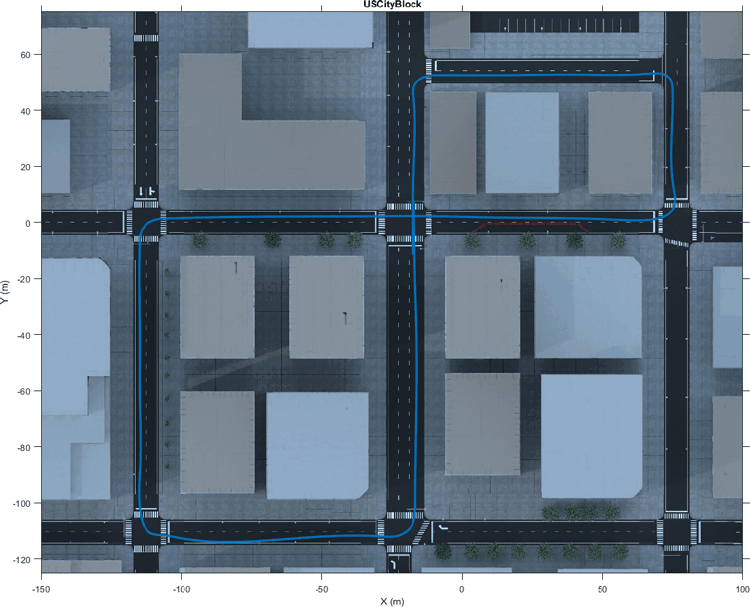

The UAVVisual`SLAMIn3DSimulation` Simulink® model is configured with the US City Block scene using the [Simulation 3D Scene Configuration](docid:uav_ref#mw_96a521fd-316f-497b-bc01-b2c5f4083563) block. The model places a UAV on the scene using the [Simulation 3D UAV Vehicle](docid:uav_ref#mw_619937da-a01b-431e-88b5-4f39caf0b95a) block. A stereo camera consisting of two [Simulation 3D Camera](docid:uav_ref#mw_e9491451-3198-4988-8ef1-6a3878d29155) blocks is attached to the UAV. In the dialog box of the [Simulation 3D Camera](docid:uav_ref#mw_e9491451-3198-4988-8ef1-6a3878d29155) block, use the **Mounting** tab to adjust the placement of the camera. Use the **Parameters** tab to configure properties of the camera to simulate different cameras. To estimate the intrinsics of the stereo camera that you want to simulate, use the [**Stereo Camera Calibrator**](docid:vision_ug#buejbxx-1) app.

% Stereo camera parameters
focalLength    = [1109, 1109]; % In pixels
principalPoint = [640, 360];   % In pixels [x, y]
imageSize      = [720, 1280];  % In pixels [mrows, ncols]
baseline       = 0.5;          % In meters

% Open the model
modelName = 'UAVVisualSLAMIn3DSimulation';
open_system(modelName);

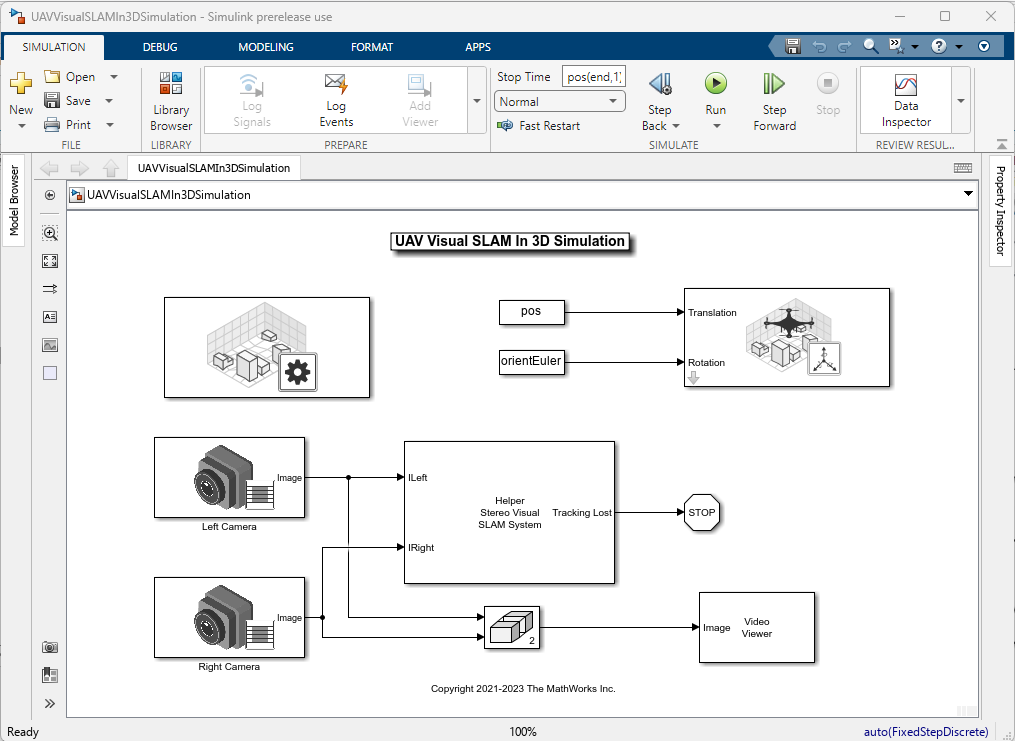

## **Run Stereo Visual SLAM Simulation**

The **Helper Stereo Visual SLAM** System block implements the stereo visual SLAM pipeline using the [`stereovlsam`](docid:vision_ref#mw_a1f117bd-1181-4809-b4e5-1ebabaca2a32) class. Simulate the model and visualize the results. 

% Set the random seed to get consistent results
rng(0);

% Run simulation
sim(modelName);

Error due to multiple causes.

Caused by:
    Error using StereoVisualSLAMForUAVNavigationIn3DSimulationExample (line 19)
    MATLAB System block 'UAVVisualSLAMIn3DSimulation/Simulation 3D Scene Configuration/Simulation 3D Engine' error occurred when invoking 'stepImpl' method of 'Simulation3DEngine'.
        Er

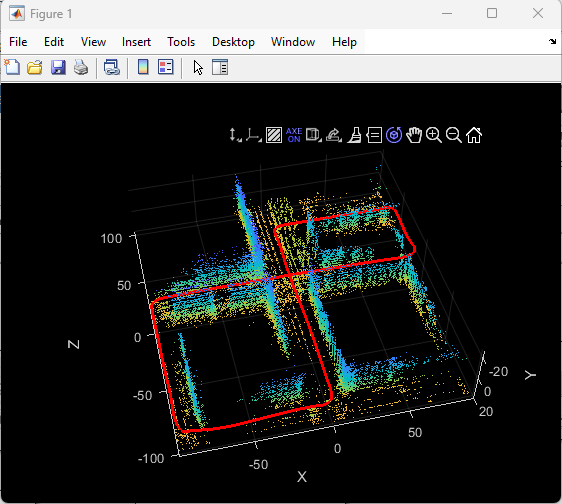

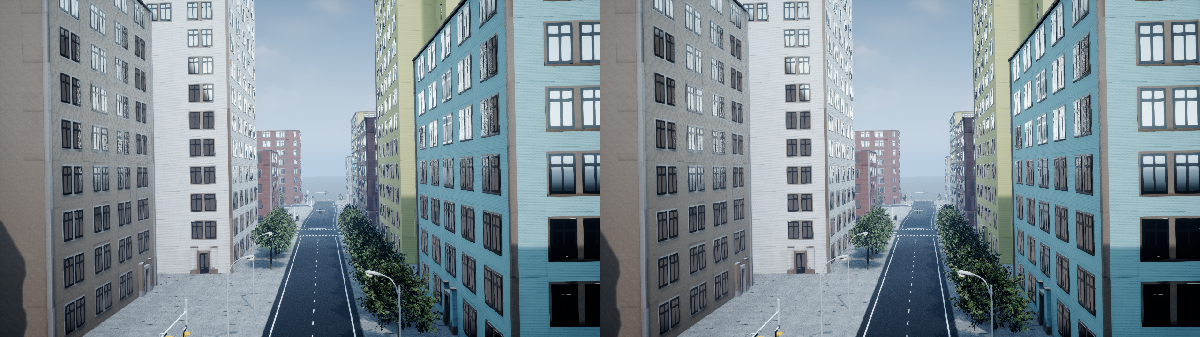

Close the model.

close_system(modelName);

## References

[1] Mur-Artal, Raul, and Juan D. Tardós. "ORB-SLAM2: An open-source SLAM system for monocular, stereo, and RGB-D cameras." *IEEE Transactions on Robotics* 33, no. 5 (2017): 1255-1262.

*Copyright 2021-2023 The MathWorks, Inc.*